**Importing previously recorded cell into the SchwartzLab database**

Overview. We need to work together to get all our previously recorded (pre-2021) data into the database. While the process will be similar for new data, I will try to make it a little more automated, so there will probably be some separate instructions. 

MeasuredCells belong to Animals. One of the powerful things about relational databases is that they contain information about the relationships between elements, like the fact that each MeasuredCell belongs to an Animal. However, this means that we cannot have orphan MeasuredCells in the database without including the Animal (and Eye) from which they came. While our Animal record-keeping from 2021 on is now part of the datajoint system, with Susan and Kayla logging information about every single animal in our colony, I recognize that this was not the case in the past. Thus it is a considerable effort (and likely impossible in most cases) to track down information like the date of birth and sex of every animal you have used. 

Therefore, you have a decision to make about cells recorded pre-2021. In some cases, details about the Animal are really important to an ongoing project. One example is Devon's project working on projections from retina to MeA. Since she needs to analyze her data based on the age and sex of the animals and the hemisphere in which she injected MeA, she cannot assign her cells to anonymous Animal entries. For many other projects, however, this is not the case. We have a huge amount of data in the lab that comes from adult (post 4 week old) mice that are either WT or "functionally" WT in the sense that some cells might be fluorescently labelled but they should not respond differently from those in WT. 

If you detemine that details about the Animal are essential to your ongoing work, DO NOT follow the rest of this guide for importing those cells. I will need to help you add the Animal entrry first. Otherwise, keep reading.

The class hierachy for animals and retinal cells looks something like this.

An sl.SymphonyRecordedCell is what we colloquially call a "cell" in the lab. It means that you have a corresponding CellData file and it was reccorded from a retina. An entry in the sl.SymphonyRecordedCell table is associated with entries in these other 4 tables. While this might seem more compllicated than it needs to be, this structure was designed with the future in mind to accomodate data like:

• MeasuredCells from the brain

• Images of an Eye or Brain

• Functional and structural imaging data from cells that may not have corresponding Symphony electrophysiology data

Batch imports. For pre-2021 cells for which the Animal data is non-essential, I wrote a "batch" importing script that creates entries in the 4 "parent" tables with minimal interaction from the user so it can be done *en masse*. For cells imported this way.

• The dob and sex of the Animal will be set to "Unknown" and the genotype will be set to WT.

• The animal will receive a DJ_ID (an arbitrary integer that serves as a unique identifier) but it will not receive a tag_id corresponding to the physical tags on the animals' ears.

• A "Deceased" AnimalEvent will be added to the database on the experiment date (as determined by the cell name) with the reason "sacrificed for experiment". 

• The script will try to extract the cell position, who did the recording, and whether it was from the left or right eye from the CellData file. It will add "Unknown" sl.Eye entries, "Unknown" as the experimenter and empty positions for the information it cannot find. In older (before mid-2017 Symphony 1) data, some of this information is not in the CellData files. 

IMPORTANT: The import relies on the CellData files, so they must be up to date and checked! This means that you should make sure that you have made Datasets (in CellDataCurator) and finished spike detection for each cell in your import list. We can replace cells that get imported from out-of-date CellData files, but it is a nuisance and will delete all Results associated with that cell. Replacing individual SpikeTrains in which spike detection got messed up is easier. 

The batchImportRecordedCells function. You can call the batch import function like this.

where fname is the name of a .txt file that contains the names of the cells - one on each line (like our current cellNames.txt files) and auto_import is a (true or false) flag that determines whether the script will try to assign cell types automatically based on the type in the CellData file (default = true) or whether it will prompt you for each one (false). If you omit fname, it will open up a dialog box so you can just navigate to the file and select it. 

The function returns 3 cell arrays that list cells that were inserted, caused an error, or were not inserted because they were already in the database. It also writes a log .txt file that you can send to me if you encounter any errors. Please note the error_cells and send me a list of them so I can figure out what went wrong.

If auto_import = false, after the function does the initial import for each cell, it will open up a dialog box that looks like this ask you to assign it a cell type. 

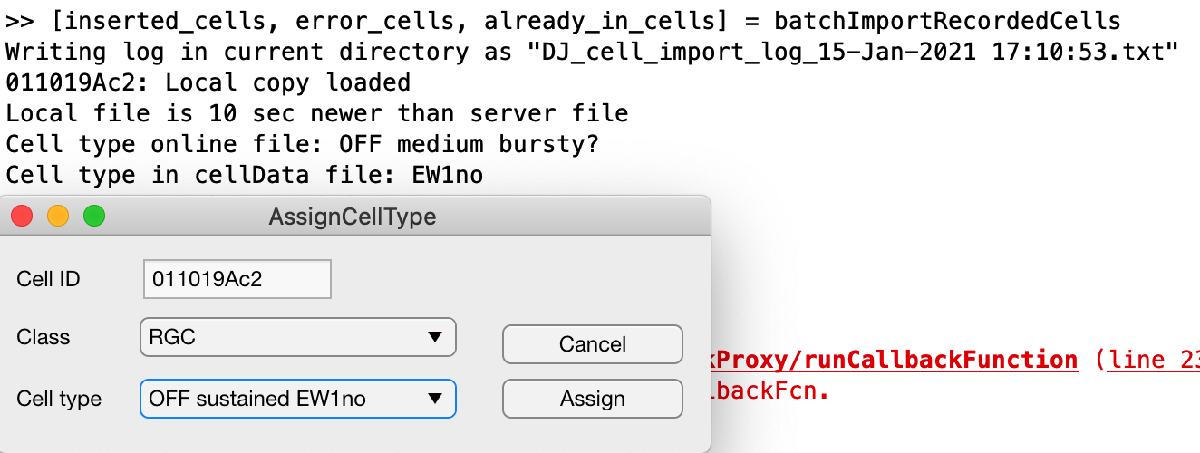

It will print on the MATLAB command line the cell type currently assigned in the CellData file and what was written about the cell type at the time of recording. Select the matching CellType from the provided dropdown menu or "Unknown" if you don't know.  For example, at the time of the recording, someone wrote "OFF medium bursty?" for this cell. It was later assigned as "EW1no" in the CellData file. The corresponding CellType in the database is called "OFF sustained EW1no", so I will select that and press "Assign". Remember that we can change CellTypes after the cells are imported, so it is not a big deal if you make a mistake. 

Importing Epochs, Datasets, and SpikeTrains

Once this batchImportRecordedCells function complets, there are two more steps to the import process: 1) importing datasets and epochs from the CellData file and 2) importing spike trains from the CellData file. Both are done by calling: 

This command will look for all inserted cellls that have not been imported in the whole database and then it will do the same for SpikeTrains. However, you should not have to do this yourself since there is a script running on the server that runs this function continuously. You can check if it has completed for your cell like this. Let's assume your cell of interest is the one shown in the example above: 011019Ac2.

sl.SymphonyRecordedCell & 'cell_id="011019Ac2"'

This will list the recorded cell entry and the number_of_epochs field should say 139 for this cell.

sl.Dataset & 'cell_id="011019Ac2"'

This will list the datasets. There are 5 datasets for this cell.

sl_mutable.SpikeTrain & 'cell_id="011019Ac2"'

This will list the loaded SpikeTrains. All the epochs in datasets in this cell are cell-attached, so there are 139 SpikeTrains, the same as the number of epochs. If some of your data is whole-cell you will have fewer SpikeTrains than epochs. 

If it looks like the "populateAll" command has failed, let me know, and I can check its status on the server. It prints a log file here if you want to look yourself for an error: